# create downsampled vector of all aluminum times without the artifact times

run(params_path)

experiment = auditory_ephys_exp(params_path);

data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
aud_data = data.Data.Data.mapped(32 + mic,:)

% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame
expLength = length(data.Data.Data.mapped)
whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)
whiskingVector = [whiskingStart:whiskingEnd]
sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))
faceVector = [faceStart:faceStart+length(whiskingVector)-1]

### If there is a mistake in extracting condition changes, please correct it here

- `Check how many were missed`

- `Check the condition missed class with the camera`

- `identify the condition change in the sound `

- `Split the conditions and clasiffy them in experiment.conditions`

% if needed use this space for corrections
  experiment.Conditions.condition_classification = [experiment.Conditions.condition_classification(1:8);1;experiment.Conditions.condition_classification(9:end)]
  experiment.Conditions.all_changes = [experiment.Conditions.all_changes(1:8);g;experiment.Conditions.all_changes(9:end)]

% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30
artifactEnd = experiment.Conditions.artifact_times(1) * 30
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]
aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)
% create idx vector for aluminum
aluminumInd = []
for al = 1:length(aluminumTimes)
    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))
    aluminumInd = [aluminumInd;tempInd]
end

% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)
% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'
% create video frame face vector
aluminumFaceVector = faceVector(aluminumInd)'

## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
aud_data = data.Data.Data.mapped(34,:)

mkdir analysis
cd analysis
audiowrite("aud_data.wav",aud_data,30000)

figure; plot(aud_data ...
    )

%filter data and keep just the aluminum sound componenets
[b,a] = cheby1(5,20,[1000]/15000,'high');
aud_data_filt = filtfilt(b,a,double(aud_data));

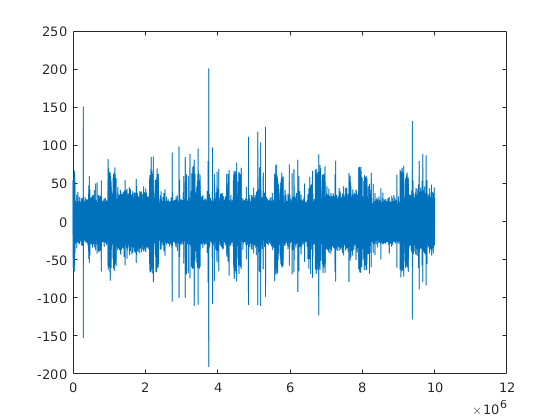

figure; plot(aud_data_filt(10000000:20000000))

aud_denoise = wdenoise(aud_data_filt,2,'DenoisingMethod','BlockJS');

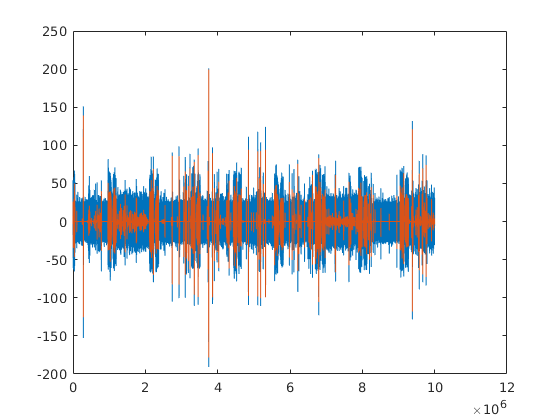

hold on; plot(aud_denoise(10000000:20000000))

% clean artifacts clipping
figure; plot(aud_denoise(10000000:20000000))

for art = 1:length(all_times)
    chg_time = experiment.Conditions.all_changes(art);
    aud_data_filt(chg_time-artifactEnd:chg_time+artifactStart) = median(aud_denoise);
end

hold on; plot(aud_denoise(10000000:20000000))

aud_denoise = wdenoise(aud_data_filt)

aud_denoise = 	1.0e+03 *

   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


% envelope aud_data
aud_data_env = envelope(aud_data_filt,300,"analytic");

figure; plot([1:10000001]/30000,aud_denoise(10000000:20000000))
hold on; plot([1:10000001]/30000,aud_data_env(10000000:20000000))

% filter envelope to gte only slow changes
[bn,an]  = butter(5,[200]/15000,'low');
aud_data_env = filtfilt(bn,an,double(aud_data_env));

aud_data_cleaned = normalize(aud_data_env,'range',[0,1]);

figure;plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)


% clean data below threshold
%aud_data_cleaned(aud_data_cleaned<0.11) = median(aud_data_cleaned);


figure; plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)

experiment.sound_events.fullSound = aud_data;
experiment.sound_events.fullSoundCleaned = aud_data_cleaned;

aud_data_Alum = aud_data_cleaned(aluminumVector)

%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_Alum)

cd analysis/

save('FVB103_849.mat',"experiment")

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)
[b,a] = butter(3,[2 400]/15000,'bandpass')
encoder_data = filtfilt(b,a,double(encoder_data))

figure; plot(encoder_data)

encoder_data = normalize(envelope(encoder_data),'range',[0,1])

% import the whisking moiton vectors
[file,path] = uigetfile();
cd(path)
load(file,'motSVD_1','motion_1')

% add encoder to the modal and prediction matrices
modelMatrix = encoder_data(aluminumVector)'
predictionMatrix = encoder_data(sampleVector)'


motSVD_1(:,1:500) = normalize(envelope(motSVD_1),'range',[0,1])
motion_1 = normalize(envelope(motion_1),'range',[0,1])

modelMatrix(:,1) = motion_1(aluminumWhiskerVector)

modelMatrix(:,2:501) = motSVD_1(aluminumWhiskerVector,1:500)


predictionMatrix(:,2) = motion_1(whiskingVector)
predictionMatrix(:,3:252) = motSVD_1(whiskingVector,1:500)

clearvars -except modelMatrix aud_data_Alum predictionMatrix sampleVector aluminumWhiskerVector whiskingVector

modelMatrix_0 = single(lagmatrix(modelMatrix,[-20:4:0]))
modelMatrix_1 = single(lagmatrix(modelMatrix,[4:4:20]))

modelMatrix = [];

modelMatrix = [modelMatrix_0,modelMatrix_1]

% predictionMatrix_0 = single(lagmatrix(predictionMatrix,[-100 50 0]))
% predictionMatrix_1 = single(lagmatrix(predictionMatrix,[50 100]))
% predictionMatrix = [predictionMatrix_0,predictionMatrix_1]
% predictionMatrix(isnan(predictionMatrix)) = 0

% save the model and prediction vectors 

save('model_matrices.mat','modelMatrix',"aud_data_Alum",'predictionMatrix','sampleVector','aluminumWhiskerVector','whiskingVector','-v7.3')


clearvars -except modelMatrix aud_data_Alum predictionMatrix sampleVector aluminumWhiskerVector whiskingVector

figure; plot(aud_data_Alum)

hold on; plot(modelMatrix(:,1500 ...
    )/50)

fullModel = modelMatrix

fullModel(:,1261) = aud_data_Alum

modelMatrix = fullModel([1001:15000,80000:90000,115000:125000,143000:148000,187000:193000,204000:216000],:)

%Annotate quiet periods and movement periods
%Annotate quiet periods and movement periods
% movement_times = [68701,183210;191871,203690;206091,207420;209481,223930]
% quiet_times = [1,68700;183211,191870;203691,206090;207421,209480;223931,229040]

% split modelMatrix to quiet and movement periods and reduce the below
% threshold movement
% modelClean = [];
% model_quiet =[];
% for tt = 1:5
%         modelTemp = modelMatrix(quiet_times(tt,1):quiet_times(tt,2),:);
%         mm = cvpartition(length(modelTemp),"HoldOut",0.3);
%         idxquiet = test(mm);
%         sum(idxquiet)
%         modelTemp = modelTemp(idxquiet,:);
%         aud_below = modelTemp(:,253) < 0.2;
%         modelTemp(aud_below,253) = 0;
%         modelClean = [modelClean;modelTemp];
%     
%     if tt<4
%         model_temp = modelMatrix(movement_times(tt,1):movement_times(tt,2),:);
%         aud_below = model_temp(:,253) < 0.18;
%         modelClean = [modelClean;model_temp];
% %     sum(aud_below)
% %     model_temp = model_temp(aud_below,:);
%     end
% end

% figure; 
% plot(modelClean(:,253))

%modelClean(:,1:252) = envelope(normalize(modelClean(:,1:252)))


% figure;
% plot(modelClean(:,1))

%predictionMatrix = envelope(normalize(predictionMatrix))

% figure;
% plot(predictionMatrix(:,100))

% save("modelclean.mat","modelClean","predictionMatrix","sampleVector")

clearvars -except   modelMatrix predictionMatrix sampleVector fullModel

save('modelPartitioned.mat',"modelMatrix","fullModel")

data_length = length(modelMatrix(:,1))
data_length/400

data10 = round(0.1*data_length)
data10/400
lengthTestSection = round(data10/5)

testStarts = randperm(data_length,5)
testEnds = testStarts+lengthTestSection
idxTest =[];
for tt = 1:5
    testTemp = testStarts(tt):testEnds(tt)
    idxTest = [idxTest,testTemp]
end

idxTest = ismember(1:data_length,idxTest)
idxTrain = ~idxTest

    % split data to train test
modelTrain = modelMatrix(~idxTest,:)
modelTest = modelMatrix(idxTest,:)

%aud_data_Train = aud_data_Alum(idxTrain)
%aud_data_test = aud_data_Alum(idxTest)

Mdl = fitrensemble(modelTrain(:,2:502),modelTrain(:,503),"Method","Bag","CrossVal","on","Options",statset("UseParallel",true))

figure;
plot(modelTest(:,503))

figure;
plot(modelTrain(:,503))

save('modelPartitioned.mat',"modelTest","modelTrain")

24604/60/60